### Exploración Inicial - EEG de Temple University (TUH)

ruta = 'F:\MAFER\UVG\TRABAJO DE GRADUACIÓN MECATRÓNICA\DATA_EEG_TUH\tuh_eeg_abnormal\v3.0.1\edf\eval\abnormal\01_tcp_ar\aaaaabdo_s003_t000.edf'

ruta = 'F:\MAFER\UVG\TRABAJO DE GRADUACIÓN MECATRÓNICA\DATA_EEG_TUH\tuh_eeg_abnormal\v3.0.1\edf\eval\abnormal\01_tcp_ar\aaaaabdo_s003_t000.edf'

tt = edfread(ruta)

tt = 1217×30 timetable
    Record Time      EEGFP1_REF        EEGFP2_REF        EEGF3_REF         EEGF4_REF         EEGC3_REF         EEGC4_REF         EEGP3_REF         EEGP4_REF         EEGO1_REF         EEGO2_REF         EEGF7_REF         EEGF8_REF         EEGT3_REF         EEGT4_REF         EEGT5_REF         EEGT6_REF         EEGA1_REF         EEGA2_REF         EEGFZ_REF         EEGCZ_REF         EEGPZ_REF         EEGROC_REF        EEGLOC_REF       EEGEKG1_REF        EEGT1_REF         EEGT2_REF         PHOTIC_REF  

info = edfinfo(ruta);

info.SignalLabels

ans = 30×1 string array
    "EEG FP1-REF"
    "EEG FP2-REF"
    "EEG F3-REF"
    "EEG F4-REF"
    "EEG C3-REF"
    "EEG C4-REF"
    "EEG P3-REF"
    "EEG P4-REF"
    "EEG O1-REF"
    "EEG O2-REF"
    "EEG F7-REF"
    "EEG F8-REF"
    "EEG T3-REF"
    "EEG T4-REF"
    "EEG T5-REF"
    "EEG T6-REF"
    "EEG A1-REF"
    "EEG A2-REF"
    "EEG FZ-REF"
    "EEG CZ-REF"
    "EEG PZ-REF"
    "EEG ROC-REF"
    "EEG LOC-REF"
    "EEG EKG1-REF"
    "EEG T1-REF"
    "EEG T2-REF"
    "PHOTIC-REF"
    "IBI"
    "BURSTS"
    "SUPPR"


fs = info.NumSamples/seconds(info.DataRecordDuration)

fs =    250
   250
   250
   250
   250
   250
   250
   250
   250
   250
   250
   250
   250
   250
   250


recnum = 1;
signum = 1;
t = (0:info.NumSamples(signum)-1)/fs(signum);
y = tt.(signum){recnum};

plot(t,y)
legend(strcat("Record ",int2str(recnum), ...
    ", Signal ",info.SignalLabels(signum)))
hold on

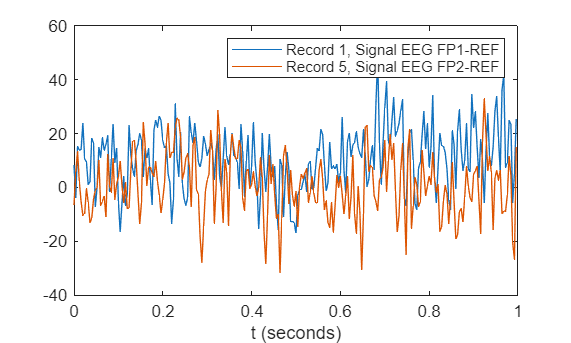

recnum = 5;
signum = 2;
t = (0:info.NumSamples(signum)-1)/fs(signum);
y = tt.(signum){recnum};

plot(t,y, ...
    'DisplayName',strcat("Record ",int2str(recnum), ...
    ", Signal ",info.SignalLabels(signum)))
hold off
xlabel('t (seconds)')